clear; clc;
% cd ~/git/hardDiskControl/discreteTimeControl/
load ../data/sysDT.mat
load ../data/sysCT.mat
load ../data/Gz.mat
load ../data/plantTF.mat

Kd = [sysDT.B sysDT.A*sysDT.B sysDT.A^2*sysDT.B sysDT.A^3*sysDT.B];

discrete system is controllable, which means all poles can be arbitrarily placed.

load ../data/sysCT.mat
Kd = [sysDT.B sysDT.A*sysDT.B sysDT.A^2*sysDT.B sysDT.A^3*sysDT.B];

we will design in CT because the A matrix is much easier to work, and it is easier to place the poles to be conform the controller requirements, like overshoot.

In a 2d system, there can be only one complex conjugate pole pair. Hence, there we can perfectly comute the behaviour of the system. However, with a 4d system this becomes harder. What we can however do is place our non-dominant pole pair well withing the pole placement restrictions for the desired behaviour and we should be fine. THe dominat pole pair can than be placed a little less agressively compared to where we ould place the 2d system.

For intuition's sake we will do this in continuous time and then compute the corresponsing z-domain locations afterwards. Because the discretised system's dynamics is also subject to the sampling time we might have to reduce optimality a little bit for the sake of stability.

riseTime = 0.052333; %seconds
Ts = riseTime/10;

maxDamp = -log(0.05)/sqrt(pi^2+log(0.05)^2);
degMaxDamp = rad2deg(acos(maxDamp));

mag1 = 30;
phase1 = degMaxDamp;
pole1 = -mag1*cosd(phase1)+mag1*sind(phase1)*1i;
pole1c = -mag1*cosd(phase1)-mag1*sind(phase1)*1i;

mag2 = 55;
phase2 =degMaxDamp/5;
pole2 = -mag2*cosd(phase2)+mag2*sind(phase2)*1i;
pole2c = -mag2*cosd(phase2)-mag2*sind(phase2)*1i;

poles = [pole1; pole1c; pole2 ;pole2c];

clear mag1 phas1 pole1c mag2 phase2 pole2 pole2c;

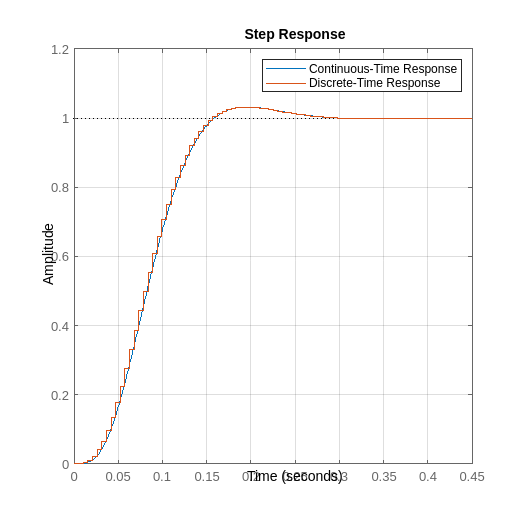

[F, prec] = place(sysCT.A,sysCT.B,poles);
AplacedCT = sysCT.A-sysCT.B*F;
sysCT = ss(AplacedCT,sysCT.B,sysCT.C,sysCT.D);
sysCT.B = sysCT.B/dcgain(sysCT);

zPoles = exp(poles.*Ts);
[F, prec] = place(sysDT.A,sysDT.B,zPoles);
Aplaced = sysDT.A-sysDT.B*F;
sysDT = ss(Aplaced,sysDT.B,sysDT.C,sysDT.D,Ts);
sysDT.B = sysDT.B/dcgain(sysDT);

figure('Position', [0 0 1000 1000]); clf; hold on;
step(sysCT)
step(sysDT); grid on;
legend("Continuous-Time Response","Discrete-Time Response")


stepinfo(step(sysDT))

ans = struct with fields:
         RiseTime: 17.1607
    TransientTime: 45.0828
     SettlingTime: 45.0828
      SettlingMin: 0.9196
      SettlingMax: 1.0319
        Overshoot: 3.2074
       Undershoot: 0
             Peak: 1.0319
         PeakTime: 38


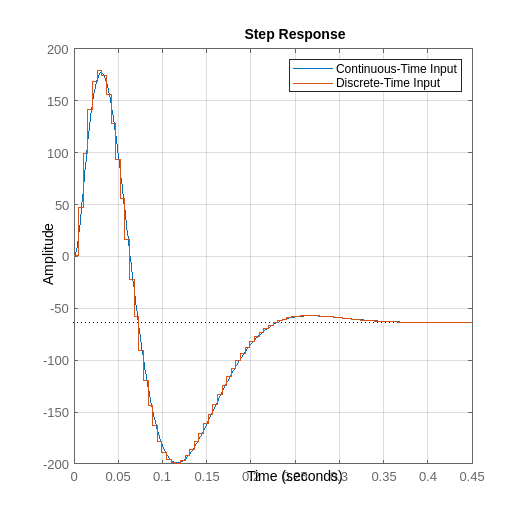


sysCT2 = ss(AplacedCT,sysCT.B,-F,1);
sysDT2 = ss(Aplaced,sysDT.B,-F,1,Ts);

figure('Position', [0 0 1000 1000]); clf; hold on;
step(sysCT2)
step(sysDT2); grid on;
legend("Continuous-Time Input","Discrete-Time Input")


stepinfo(step(sysDT))

ans = struct with fields:
         RiseTime: 17.1607
    TransientTime: 45.0828
     SettlingTime: 45.0828
      SettlingMin: 0.9196
      SettlingMax: 1.0319
        Overshoot: 3.2074
       Undershoot: 0
             Peak: 1.0319
         PeakTime: 38
